 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    4.329115e+04     0.000e+00     1.000e+00     0.000e+00     4.084e+02  
非线性约束函数返回了 Inf；正在尝试一个新点...
    1          13    3.896203e+03     3.763e+00     7.000e-01     1.174e+02     8.963e+01  
    2          19    6.128279e+03     1.486e+00     1.000e+00     1.309e+01     2.868e+02  
    3          25    7.883942e+03     4.869e-01     1.000e+00     1.382e+01     3.862e+02  
    4          31    8.973746e+03     9.276e-02     1.000e+00     8.762e+00     4.878e+02  
    5          37    9.289744e+03     4.316e-03     1.000e+00     2.697e+00     5.157e+02  
    6          43    9.311019e+03     1.873e-05     1.000e+00     1.775e-01     2.177e+01  
    7          49    9.311099e+03     2.517e-10     1.000e+00     6.614e-04     4.431e-02  
    8          55    9.311099e+03     6.661e-16     1.0

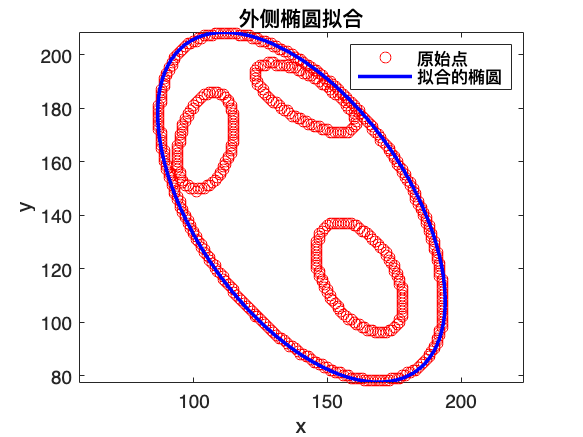

[y_raw,x_raw] = find(edges_laplacian_raw);
fit_outer_ellipse(x_raw,y_raw);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           6    3.719646e+04     0.000e+00     1.000e+00     0.000e+00     4.650e+02  
非线性约束函数返回了 Inf；正在尝试一个新点...
    1          13    3.347681e+03     2.359e+00     7.000e-01     1.178e+02     1.300e+02  
    2          19    5.814614e+03     8.084e-01     1.000e+00     1.607e+01     1.814e+02  
    3          25    8.191243e+03     1.920e-01     1.000e+00     1.257e+01     2.758e+02  
    4          31    9.227626e+03     1.892e-02     1.000e+00     5.070e+00     1.806e+02  
    5          37    9.344238e+03     2.360e-04     1.000e+00     6.024e-01     3.108e+00  
    6          43    9.345488e+03     3.652e-08     1.000e+00     7.555e-03     1.402e-01  
    7          49    9.345488e+03     4.441e-16     1.000e+00     1.165e-06     3.419e-05  



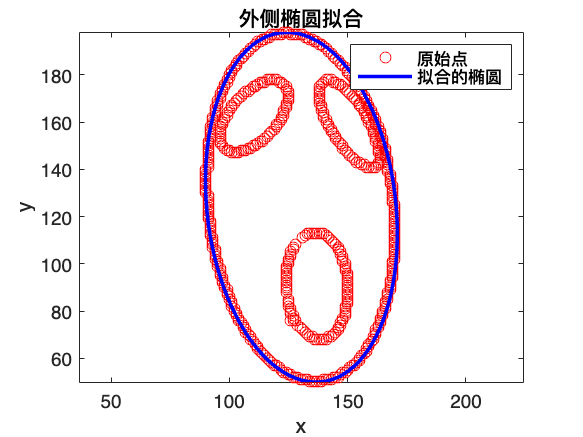

[y,x] = find(edges_laplacian);
fit_outer_ellipse(x,y);

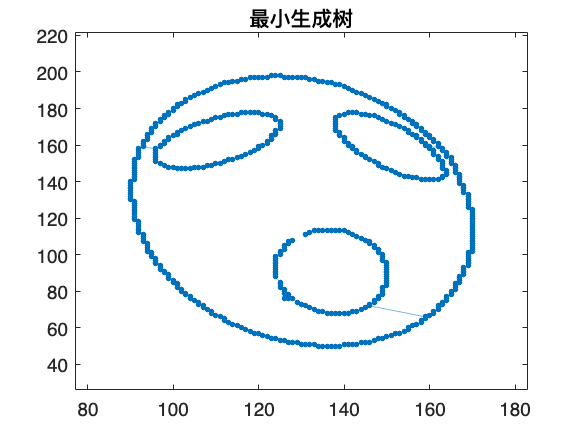


data = [x,y];

% % 设置DBSCAN参数
% epsilon = 10; % 邻域半径
% minPts = 10; % 最小点数
% 
% % 运行DBSCAN算法
% labels = dbscan(data, epsilon, minPts);
% 
% % 可视化结果
% figure;
% gscatter(data(:,1), data(:,2), labels);
% title('DBSCAN聚类结果');
% xlabel('X坐标');
% ylabel('Y坐标');
% 
% mouth = data(labels == 2,:)
% fit_outer_ellipse(mouth(:,1),mouth(:,2))

% 生成示例数据


% 计算数据点之间的距离矩阵
distMatrix = pdist(data);

% 创建加权无向图
G = graph(squareform(distMatrix));

% 计算最小生成树
mst = minspantree(G);

% 可视化最小生成树
figure;
plot(mst, 'XData', data(:,1), 'YData', data(:,2));
title('最小生成树');

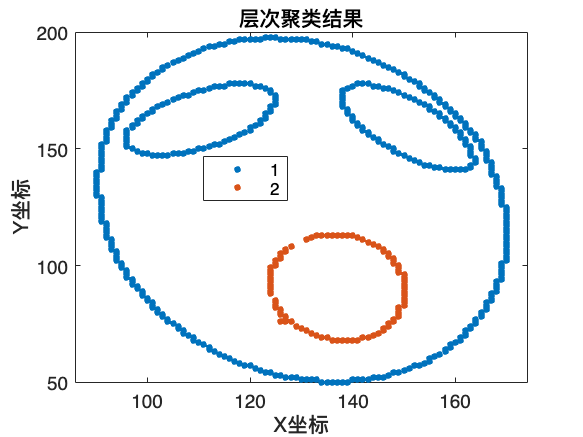


% 删除最长的边以形成两个聚类
[~, idx] = max(mst.Edges.Weight);
mst = rmedge(mst, idx);

% 获取连通分量（聚类）
bins = conncomp(mst);

% 可视化聚类结果
figure;
gscatter(data(:,1), data(:,2), bins);
title('层次聚类结果');
xlabel('X坐标');
ylabel('Y坐标');